cd('/Volumes/PrecunealSSD2/HCP/AWS/hcp-openaccess/HCP_1200');
as = mlraut.AnalyticSignalHCP( ...
    subjects={'995174'}, ...
    tasks={'rfMRI_REST1_RL'}, ...
    do_save=false, ...
    force_band=false, ...
    hp_thresh=0.005, ...
    lp_thresh=0.1, ...
    tags=stackstr(use_dashes=true), ...
    source_physio="iFV", ...
    global_signal_regression=false);

as.current_subject = as.subjects{1};
if ~contains(as.out_dir, as.current_subject)
    as.out_dir = fullfile(as.out_dir, as.current_subject);
    ensuredir(as.out_dir);
end

as.current_task = as.tasks{1};

%as.plot3()

%% parameters for aufbau

select_network_type = "cortical";
select_rsn = 'default mode';
NETWORKS_YEO_NAMES = ...
    {'visual', 'somatomotor', 'dorsal attention', 'ventral attention', 'limbic', ...
    'frontoparietal', 'default mode', ...
    'task+', 'task-'};
bool_select_rsn = contains(NETWORKS_YEO_NAMES, select_rsn);
num_frames = 417;  % as.num_frames;

tf = (num_frames - 1)*as.tr;
t = 0:as.tr:tf;

Late Hilbert transform

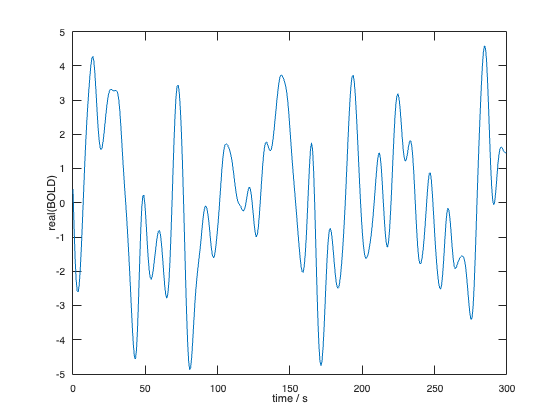

ctx = as.average_network_signal(as.task_dtseries(), network_type="cortical");
bold_gsr =  ...
    as.build_centered_and_rescaled( ...
    as.build_global_signal_regressed(ctx(:, bool_select_rsn)));

bold_ = as.build_band_passed(bold_gsr);
figure; plot(t, bold_(1:num_frames))
ylabel("real(BOLD)")
xlabel("time / s")

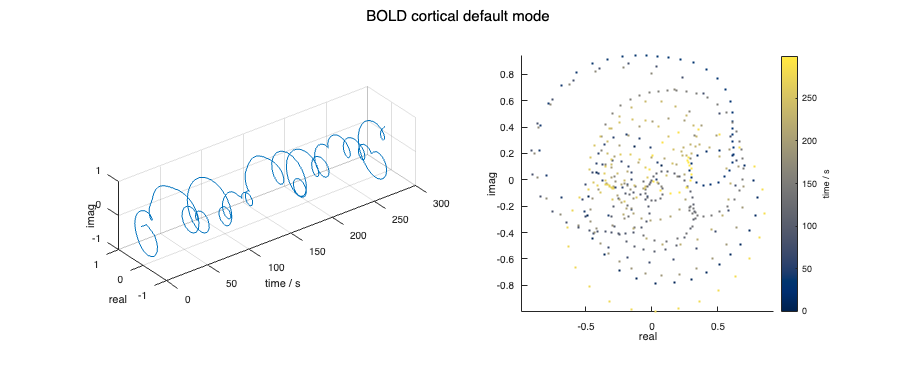


bold_signal_ = ...
    hilbert(bold_);
bold_signal__ = ...
    as.build_final_normalization( ...
    bold_signal_(1:num_frames, :));
as.plot3(num_frames=num_frames, t=t, z=bold_signal__, title="BOLD cortical " + select_rsn)

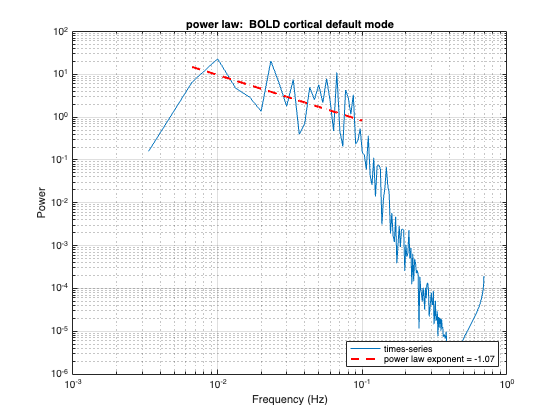

Power law exponent: -1.07


as.fit_power_law(t=t, x=bold_signal__, title="power law:  BOLD cortical " + select_rsn)

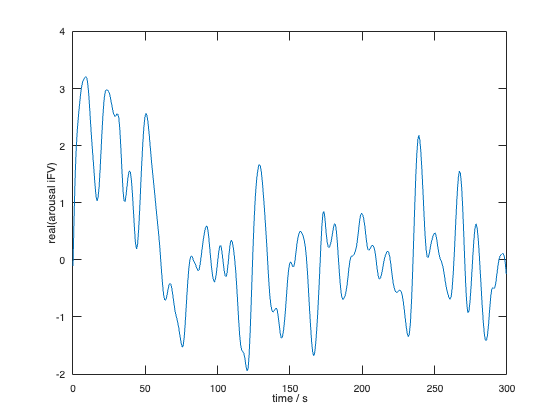

physio_gsr = ...
     as.build_centered_and_rescaled( ...
     as.build_global_signal_regressed(as.task_physio()));

physio_ = as.build_band_passed(physio_gsr);
figure; plot(t, physio_(1:num_frames))
ylabel("real(arousal iFV)")
xlabel("time / s")

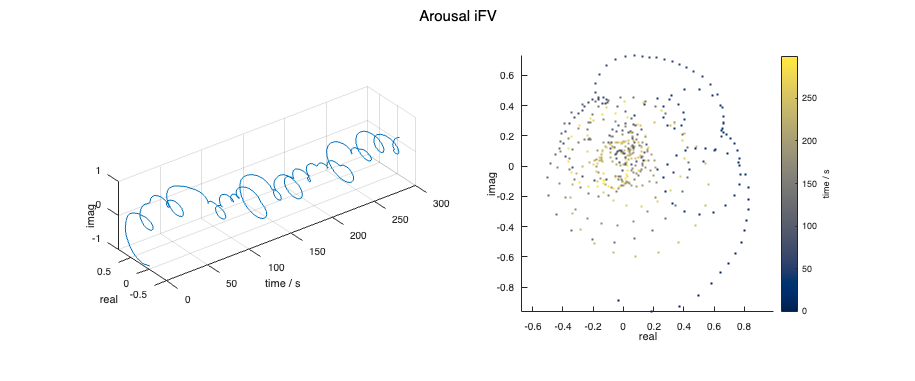


physio_signal_ = ...
    hilbert(physio_);
physio_signal__ = ...
    as.build_final_normalization( ...
    physio_signal_(1:num_frames, :));
as.plot3(num_frames=num_frames, t=t, z=physio_signal__, title="Arousal iFV")

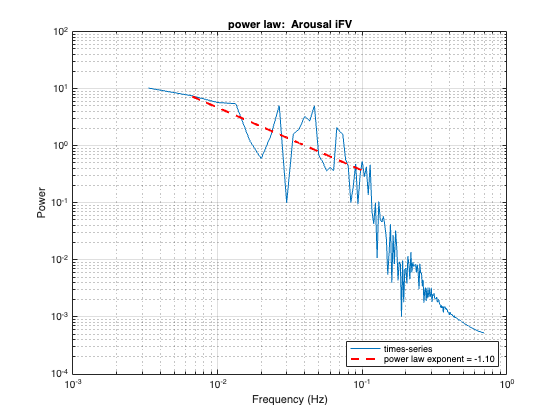

Power law exponent: -1.10


as.fit_power_law(t=t, x=physio_signal__, title="power law:  Arousal iFV")

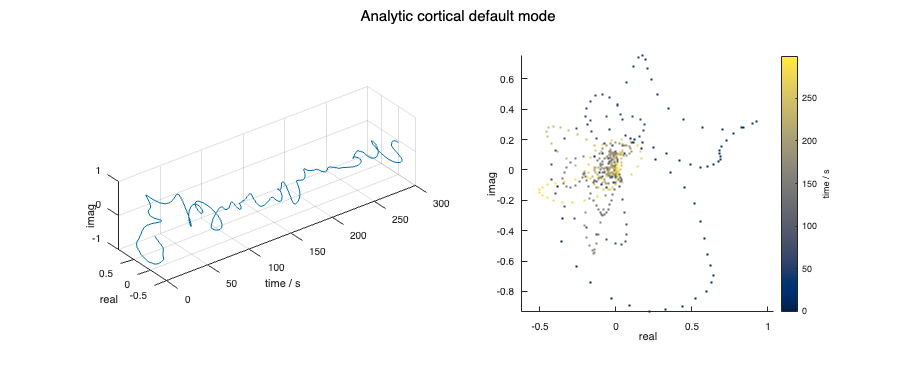

analytic_signal_ = conj(physio_signal_).*bold_signal_;

analytic_signal_ = ...
    as.build_final_normalization( ...
    analytic_signal_(1:num_frames, :));
as.plot3(num_frames=num_frames, t=t, z=analytic_signal_, title="Analytic cortical " + select_rsn)

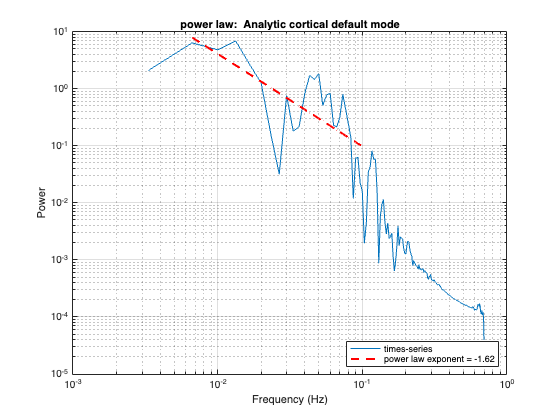

Power law exponent: -1.62


as.fit_power_law(t=t, x=analytic_signal_, title="power law:  Analytic cortical " + select_rsn)

Early Hilbert transform

ctx = as.average_network_signal(as.task_dtseries(), network_type="cortical");
bold_gsr = as.build_global_signal_regressed(ctx(:, bool_select_rsn));

bold_butter = ...
    as.build_band_passed( ...    
    as.build_centered_and_rescaled(bold_gsr));
figure; plot(t, bold_butter(1:num_frames))
ylabel("real(BOLD)")
xlabel("time / s")

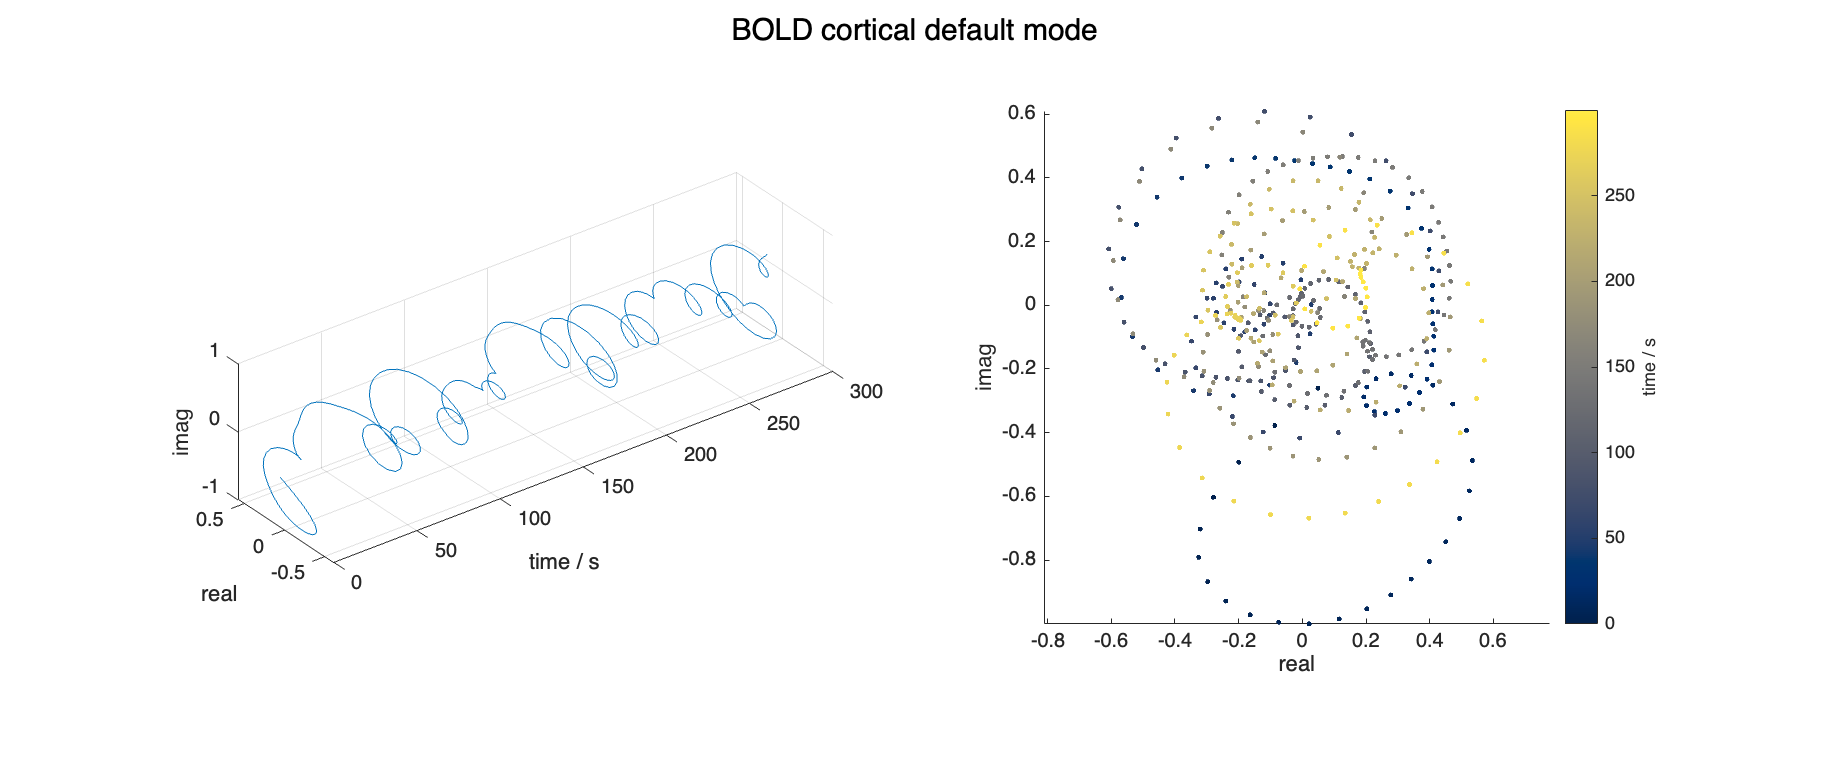


bold_signal_ = ...
    as.build_band_passed( ...
    as.build_centered_and_rescaled( ...
    hilbert(bold_gsr)));
bold_signal_ = ...
    as.build_final_normalization( ...
    bold_signal_(1:num_frames, :));
as.plot3(num_frames=num_frames, t=t, z=bold_signal_, title="BOLD cortical " + select_rsn)

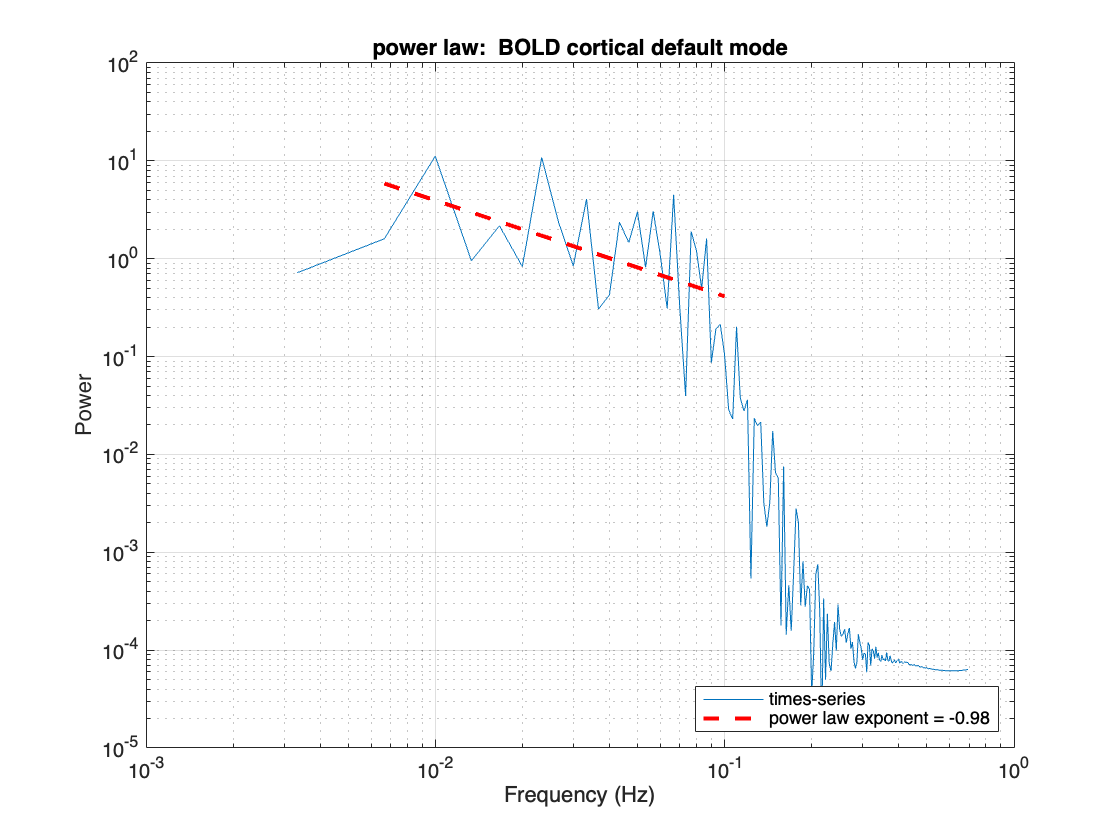

Power law exponent: -0.98


as.fit_power_law(t=t, x=bold_signal_, title="power law:  BOLD cortical " + select_rsn)

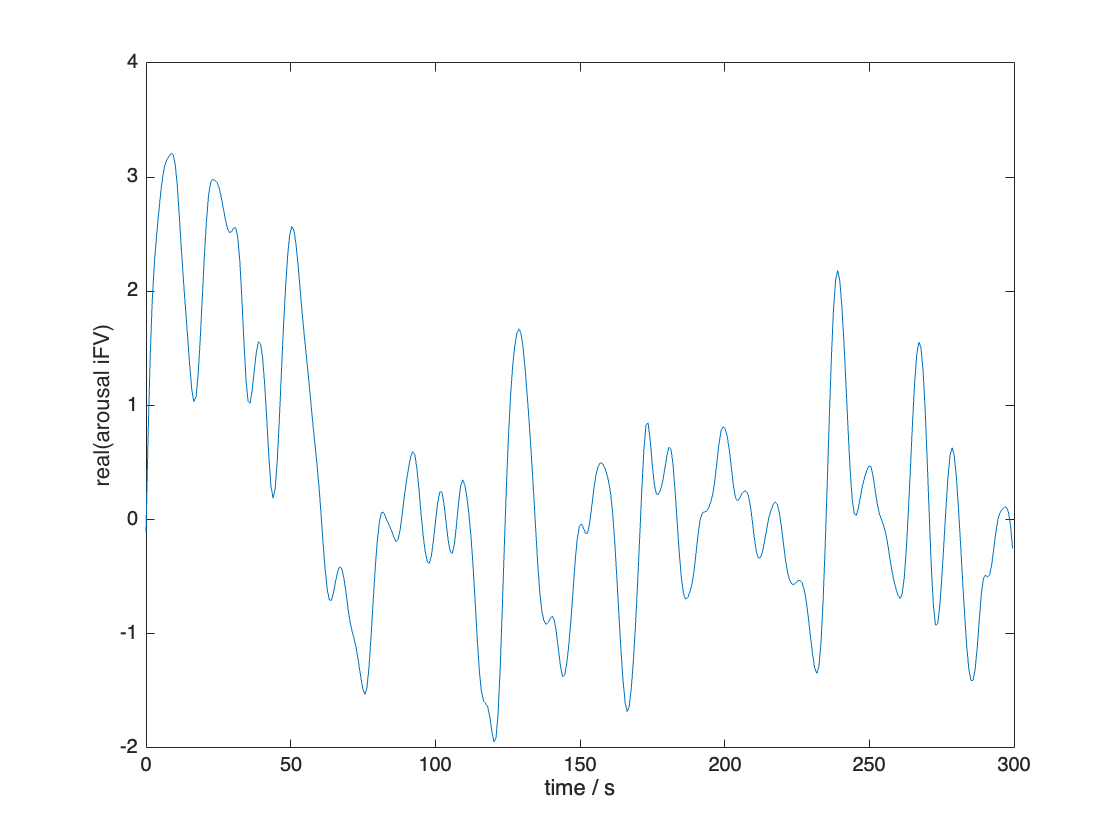

physio_gsr = as.build_global_signal_regressed(as.task_physio());

physio_butter = ...
    as.build_band_passed( ...    
    as.build_centered_and_rescaled(physio_gsr));
figure; plot(t, physio_butter(1:num_frames))
ylabel("real(arousal iFV)")
xlabel("time / s")

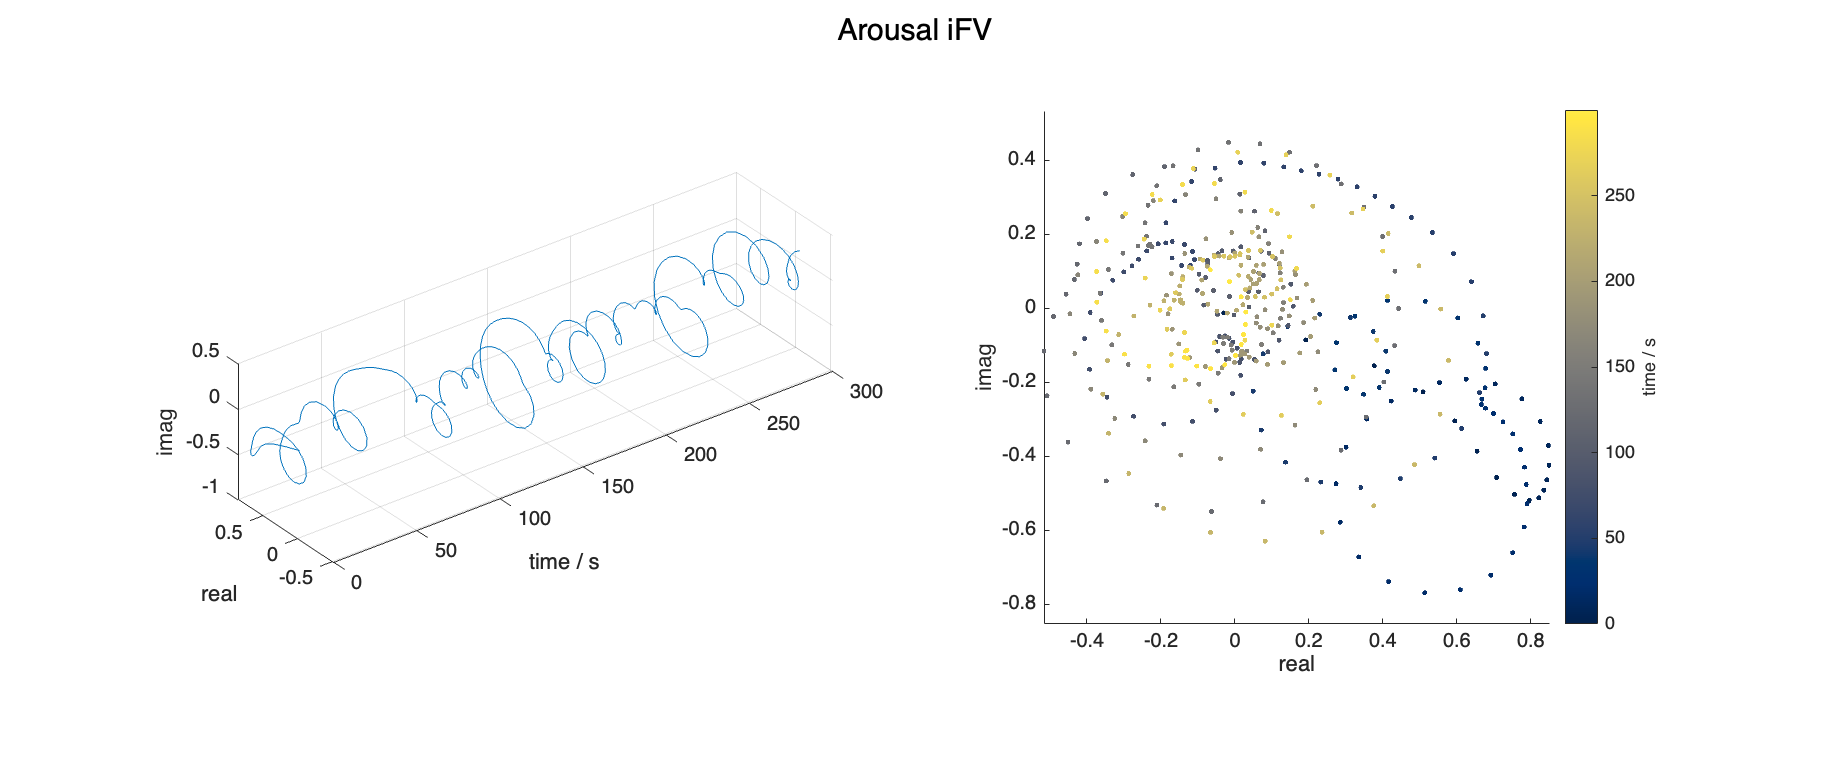


physio_signal_ = ...    
    as.build_band_passed( ...
    as.build_centered_and_rescaled( ...
    hilbert(physio_gsr)));
physio_signal_ = ...
    as.build_final_normalization( ...
    physio_signal_(1:num_frames, :));
as.plot3(num_frames=num_frames, t=t, z=physio_signal_, title="Arousal iFV")

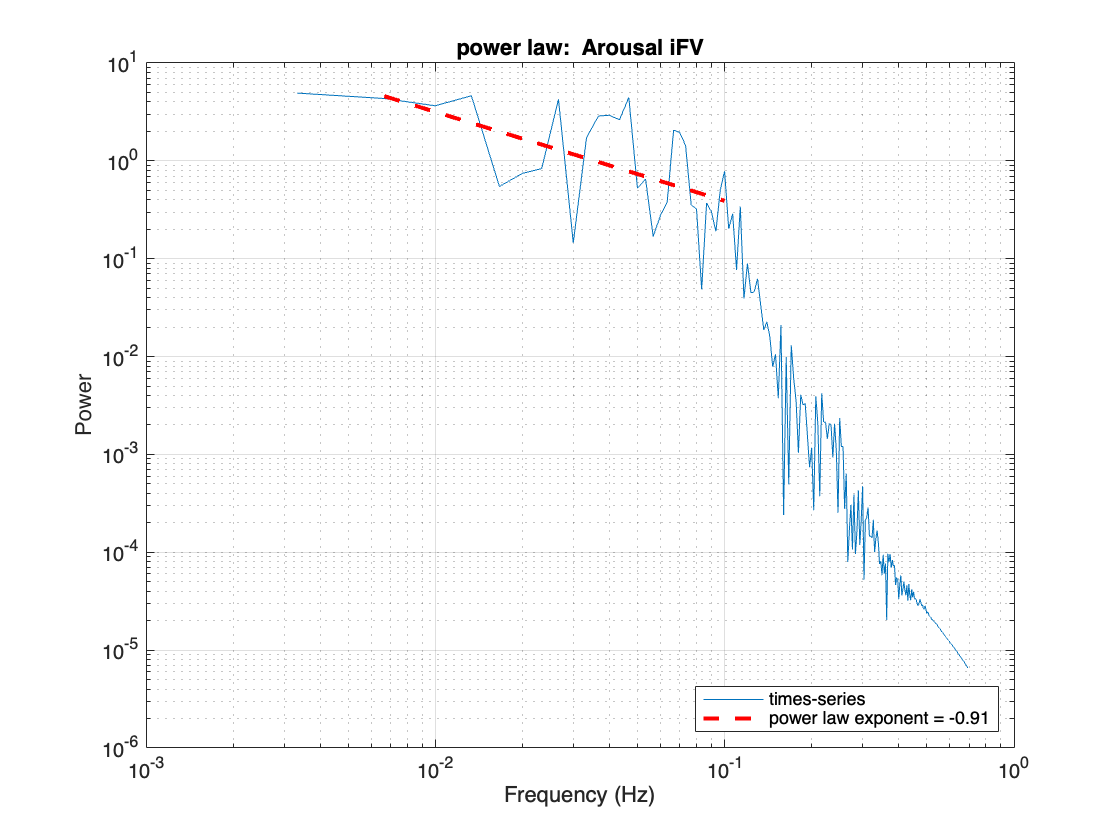

Power law exponent: -0.91


as.fit_power_law(t=t, x=physio_signal_, title="power law:  Arousal iFV")

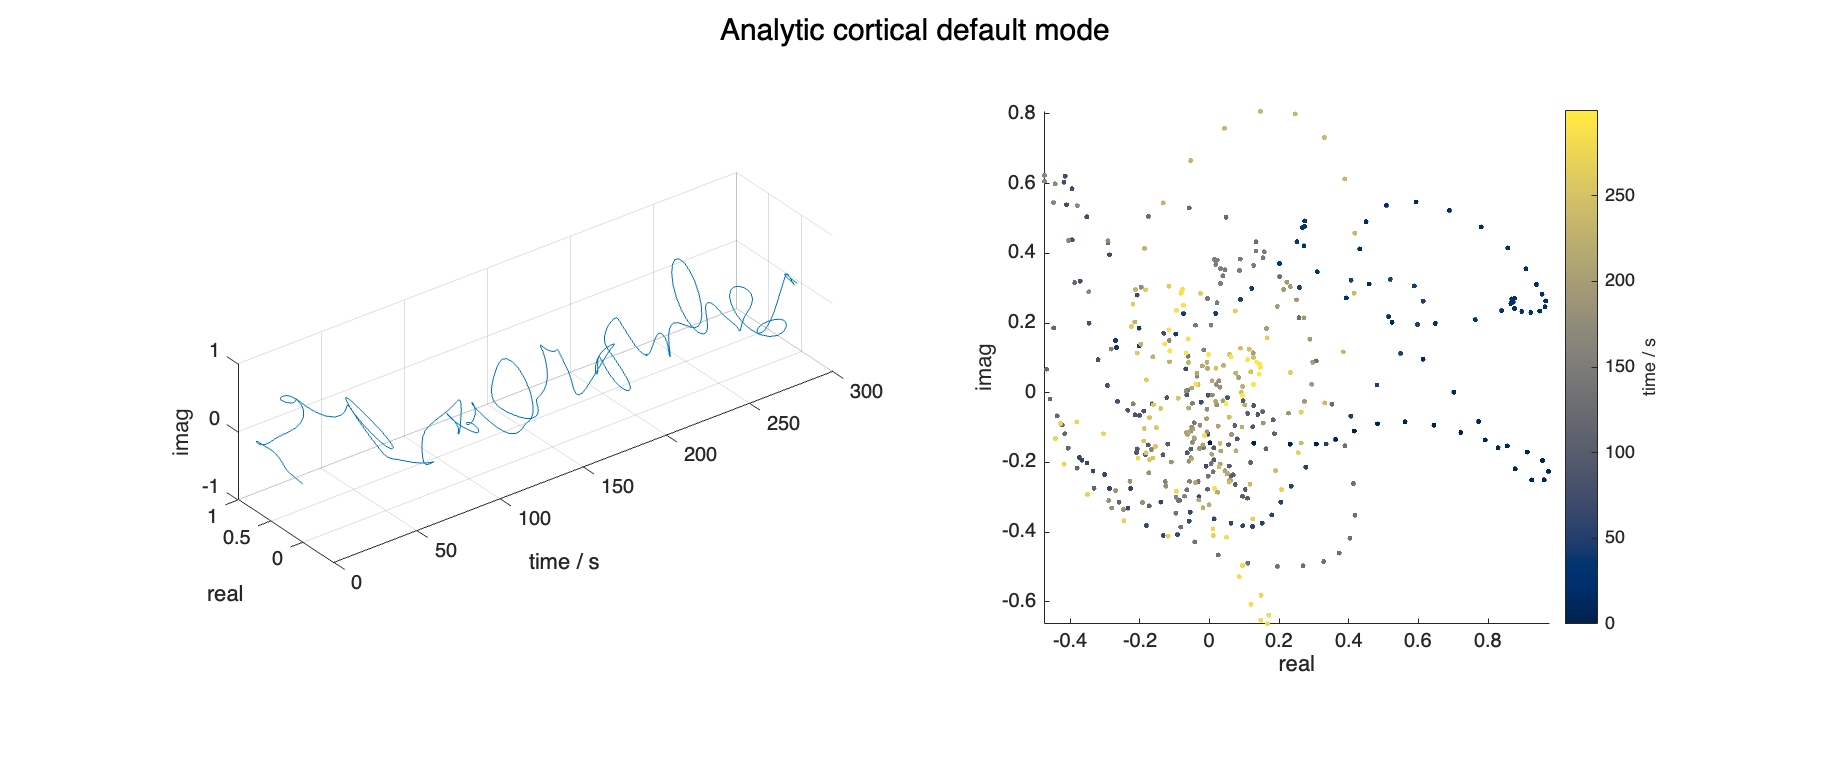

analytic_signal_ = ...
    as.build_band_passed( ...
    as.build_centered_and_rescaled( ...
    conj(hilbert(physio_gsr)).*hilbert(bold_gsr)));

analytic_signal_ = ...
    as.build_final_normalization( ...
    analytic_signal_(1:num_frames, :));
as.plot3(num_frames=num_frames, t=t, z=analytic_signal_, title="Analytic cortical " + select_rsn)

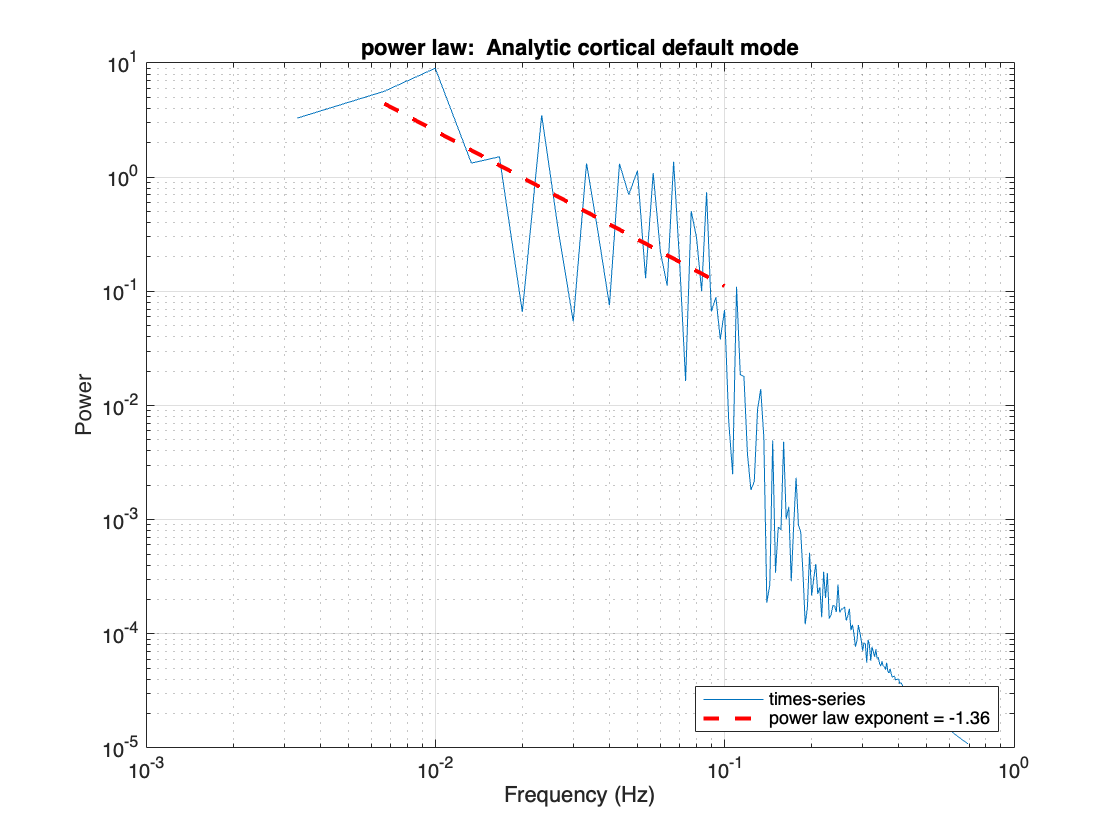

Power law exponent: -1.36


as.fit_power_law(t=t, x=analytic_signal_, title="power law:  Analytic cortical " + select_rsn)